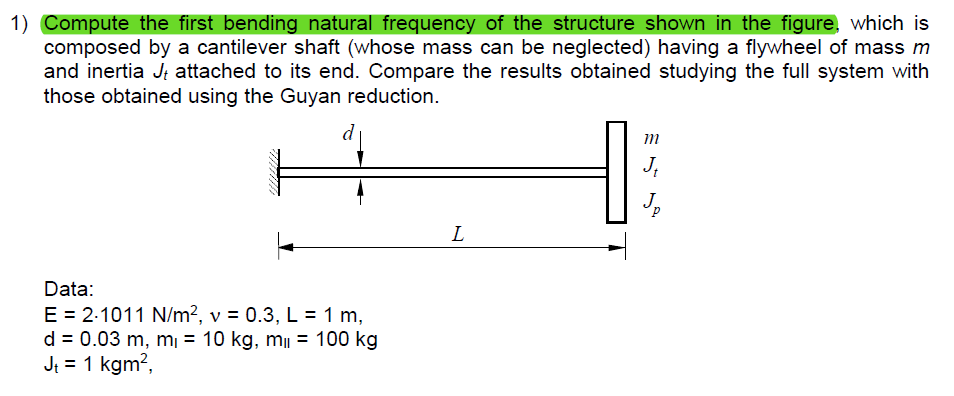

syms E v l Iy Jp m l w d

l=1

l = 1

d=0.03    %m

d = 0.0300

The mass of the beam is negligible compared to the importance of the one of the Flywheel

E=2e11 

E = 2.0000e+11

ni=0.3

ni = 0.3000


Iy=pi()*d^4/64

Iy = 3.9761e-08

A=pi()*d^2/4

A = 7.0686e-04

r_inertia=sqrt(Iy/A)

r_inertia = 0.0075

slenderness=l/r_inertia

slenderness = 133.3333

Slenderness verification since the slenderness is higher than 50 the euler bernoulli model is super suitable.

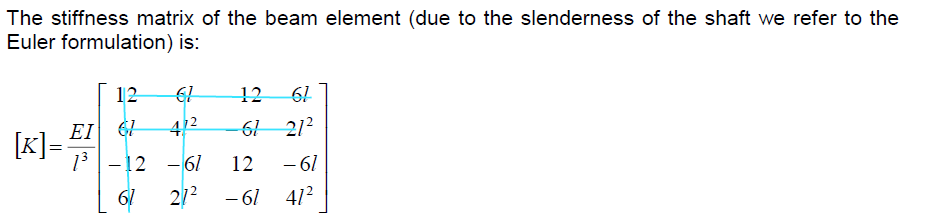


m=10%change for solution

m = 10

Jt=1

Jt = 1

M=[m 0;0 Jt]

M =     10     0
     0     1


K=(E*Iy/l^3)*[12 -6*l;
             -6*l 4*l^2]

K = 	1.0e+04 *

    9.5426   -4.7713
   -4.7713    3.1809



% D=inv(M)*K

D = 	1.0e+04 *

    0.9543   -0.4771
   -4.7713    3.1809


eqn=det(-M*w^2+K)==0;
% 
w_sol=solve(eqn);


double(w_sol)

ans =    43.8714
  198.5611
  -43.8714
 -198.5611



% 
% M_cond=M(1,1)+K(1,2)*1/K(2,2)*M(2,2)*1/K(2,2)*K(1,2)'
% Kcond=K(1,1)-K(1,2)*1/K(2,2)*K(2,1)
% 
% sqrt(Kcond/M_cond)